# Formula lui Taylor

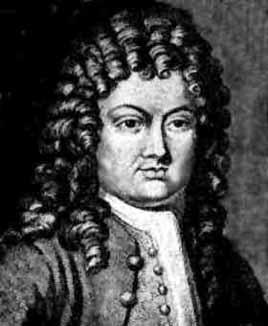   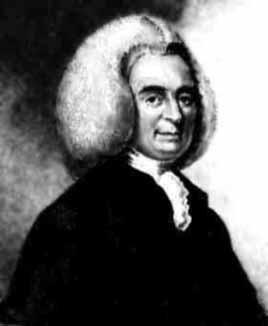

         Brook Taylor (1685-1731)                      Colin MacLaurin (1698-1738)

## P1. Radical

Să se scrie formula lui MacLaurin pentru funcția $f:[-a,\infty]\rightarrow\mathbb{R}$, $f(x)=\sqrt{a+x}$, $a>0$.

Scriem funcția sub forma $\sqrt{a+x}=a^{\frac{1}{2}} {\left(1+\frac{x}{a}\right)}^{\frac{1}{2}}$ și folosim dezvoltarea pentru seria binomială.

syms a x
assume(a);
sympref('PolynomialDisplayStyle','ascend');
a^(1/2)*taylor((1+x/a)^(1/2),x,'Order',8)

$$ans = \sqrt{a}\,\left(\frac{x}{2\,a}-\frac{x^{2}}{8\,a^{2}}+\frac{x^{3}}{16\,a^{3}}-\frac{5\,x^{4}}{128\,a^{4}}+\frac{7\,x^{5}}{256\,a^{5}}-\frac{21\,x^{6}}{1024\,a^{6}}+\frac{33\,x^{7}}{2048\,a^{7}}+1\right)$$

## P2. Exponențiala

Să se determine numărul natural $n$ astfel ca pentru $a=0$ și $f:\mathbb{R}\rightarrow\mathbb{R}$, $f(x)=e^x$, $T_nf$ să aproximeze $f(x), ~x \in [-1,1]$  cu trei zecimale exacte.

Restul trebuie să verifice condiția $\left|\left(R_n f\right)\left(x\right)\right|<{10}^{-3}$. Deoarece $\theta x<1$, $e^{\theta x}<e<3$, avem


$$\left| \frac{x^{n+1}}{(n+1)!}e^{\theta x}\right|<\frac{3}{(n+1)!}<\frac{1}{1000}$$


de unde rezultă $n=6$.

syms x n
et=taylor(exp(x),x,0,'Order',7)

$$et = 1+x+\frac{x^{2}}{2}+\frac{x^{3}}{6}+\frac{x^{4}}{24}+\frac{x^{5}}{120}+\frac{x^{6}}{720}$$

Evaluăm restul:

for n=3:8 
    disp([n,3/factorial(n+1)])
end

    3.0000    0.1250

    4.0000    0.0250

    5.0000    0.0042

    6.0000    0.0006

    7.0000    0.0001

    8.0000    0.0000



În particular, pentru $x=1$ se obține:

ap=subs(et,x,1)

$$ap = \frac{1957}{720}$$

double(abs(ap-exp(1)))

ans = 2.2627e-04

## P3. Seria binomială

Să se aproximeze $\sqrt[3]{999}$ cu 12 zecimale exacte.

Se observă că $\sqrt[3]{999}=\sqrt[3]{1000-1}=10\left(1-\frac{1}{1000} \right)^\frac{1}{3}$.

Vom folosi seria binomială cu exponentul $\alpha=\frac{1}{3}$ și $x=-\frac{1}{1000}$.

syms f ty oo3 n
oo3=sym('1/3');
f(x)=(1+x)^(1/3);
10*taylor(f(x), x, sym(0))

$$ans = 10+\frac{10\,x}{3}-\frac{10\,x^{2}}{9}+\frac{50\,x^{3}}{81}-\frac{100\,x^{4}}{243}+\frac{220\,x^{5}}{729}$$

Seria fiind alternată, eroarea va fi mai mică decât ultimul termen neglijat $|(R_{n}f)(x)|<\left\vert {\frac{1}{3}\choose {n}}10^{-3n}\right\vert$.

R=abs(nchoosek(oo3,n)*10^(-3*n));
double(subs(R,n,3))

ans = 6.1728e-11

double(subs(R,n,4))

ans = 4.1152e-14

Deci, $n=4$ este suficient pentru a obține precizia dorită.

format long
ty=10*taylor(f(x),x,0,'Order',4);
double(subs(ty,x,-1e-3))

ans =    9.996665554938271


## P4. Sinus

Reprezentați pe același grafic funcția $f:\mathbb{R}\rightarrow\mathbb{R}$, $f(x)=\sin(x)$ și aproximantele $T_1f,T_3f,\dots,T_{11}f$

clear all
syms x
Tsin=zeros(6,1,'sym');
leg=cell(1,7);
leg{1}='$\sin x$';
fplot(@(x) sin(x),[-pi,pi]);
hold on
for k=2:7
    Tsin(k-1)=taylor(@(x) sin(x),x,sym(0),'Order',2*k-1);
    leg{k}=sprintf('$T_{%2d}$',2*k-3);
    fplot(Tsin(k-1),[-pi,pi])
end
ylim([-2,2]);
Tsin

$$Tsin = \left(\begin{array}{c} x\\ x-\frac{x^{3}}{6}\\ x-\frac{x^{3}}{6}+\frac{x^{5}}{120}\\ x-\frac{x^{3}}{6}+\frac{x^{5}}{120}-\frac{x^{7}}{5040}\\ x-\frac{x^{3}}{6}+\frac{x^{5}}{120}-\frac{x^{7}}{5040}+\frac{x^{9}}{362880}\\ x-\frac{x^{3}}{6}+\frac{x^{5}}{120}-\frac{x^{7}}{5040}+\frac{x^{9}}{362880}-\frac{x^{11}}{39916800} \end{array}\right)$$

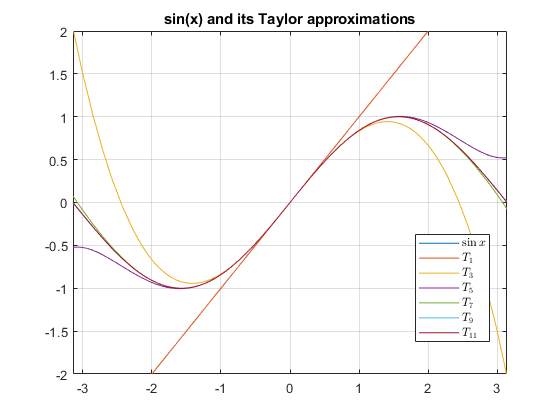

grid on
legend(leg,'Location','best','Interpreter','latex')
title('sin(x) and its Taylor approximations')
hold off

## P5. Exponențiala

Reprezentați pe același grafic funcția $f:\mathbb{R}\rightarrow\mathbb{R}$, $f(x)=\exp(x)$ și aproximantele $T_1f,T_2f,\dots,T_{5}f$ pe intervalul [-2,2]

Texp=zeros(5,1,'sym');
leg=cell(1,6);
leg{1}='$e^x$';
fplot(@(x) exp(x),[-2,2]);
hold on
for k=1:5
    Texp(k)=taylor(@(x) exp(x),x,sym(0),'Order',k+1);
    leg{k+1}=sprintf('$T_{%d}$',k);
    fplot(Texp(k),[-2,2])
end
Texp

$$Texp = \left(\begin{array}{c} 1+x\\ 1+x+\frac{x^{2}}{2}\\ 1+x+\frac{x^{2}}{2}+\frac{x^{3}}{6}\\ 1+x+\frac{x^{2}}{2}+\frac{x^{3}}{6}+\frac{x^{4}}{24}\\ 1+x+\frac{x^{2}}{2}+\frac{x^{3}}{6}+\frac{x^{4}}{24}+\frac{x^{5}}{120} \end{array}\right)$$

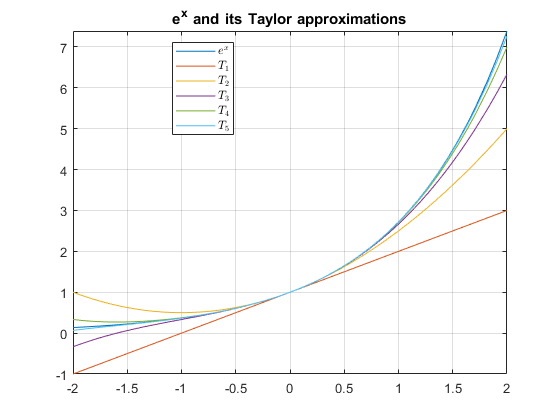

grid on
legend(leg,'Location','best','Interpreter','latex')
title(texlabel('e^x and its Taylor approximations'))
hold off

## P6. Logaritm natural

Câți termeni sunt necesari pentru a aproxima $\ln2$ cu 5 zecimale exacte?

Dezvoltarea Taylor pentru $f(x)=\ln(1+x)$, $x\in[-1,1]$ este

taylor(@(x) log(1+x),x,sym(0),'Order',11)

$$ans = x-\frac{x^{2}}{2}+\frac{x^{3}}{3}-\frac{x^{4}}{4}+\frac{x^{5}}{5}-\frac{x^{6}}{6}+\frac{x^{7}}{7}-\frac{x^{8}}{8}+\frac{x^{9}}{9}-\frac{x^{10}}{10}$$

subs(ans,x,1)

$$ans = \frac{1627}{2520}$$

Eroarea este mai mica decât $\frac{1}{n+1}$, deci pentru a aproxima $\ln 2$ cu 5 zecimale exacte vom lua $n>10^5-1=99999$ termeni.

Remediul este să considerăm dezvoltarea lui $\ln \frac{1+x}{1-x}=\ln(1+x)-\ln(1-x)$

Tf=taylor(@(x) log((1+x)/(1-x)), x, 0, 'Order',13)

$$Tf = 2\,x+\frac{2\,x^{3}}{3}+\frac{2\,x^{5}}{5}+\frac{2\,x^{7}}{7}+\frac{2\,x^{9}}{9}+\frac{2\,x^{11}}{11}$$

$x$ trebuie ales astfel ca $\frac{1+x}{1-x}=2$

solve((1+x)/(1-x)==2,x)

$$ans = \frac{1}{3}$$

Pentru a aproxima la precizia dorită, vom lua 5 termeni (gradul 9)

Tf=taylor(@(x) log((1+x)/(1-x)), x, 0, 'Order',11)

$$Tf = 2\,x+\frac{2\,x^{3}}{3}+\frac{2\,x^{5}}{5}+\frac{2\,x^{7}}{7}+\frac{2\,x^{9}}{9}$$

app=subs(Tf,x,1/3)

$$app = \frac{4297606}{6200145}$$

appf=double(app)

appf =    0.693146047390827


appf-log(2)

ans =     -1.133169118094912e-06
